clear

# India-Pakistan Arms Race Economic Constraint Model

### Data Preprocessing

First we will import the data from Expenditure.csv and ExpenditurePercent.csv into separate tables. These csv files can be found at:

- Absolute spending: [https://data.worldbank.org/indicator/MS.MIL.XPND.CD](https://data.worldbank.org/indicator/MS.MIL.XPND.CD)

- Percent of GDP: [https://data.worldbank.org/indicator/MS.MIL.XPND.GD.ZS](https://data.worldbank.org/indicator/MS.MIL.XPND.GD.ZS) 

We will extract from each of these tables the countries that have military expenditure data available from 1960-2020 with no missing values.

dataLines = [5, Inf];
timeline = 1960:2020;
yearNames = string(timeline);

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 65, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["CountryName", "CountryCode", "IndicatorName", "IndicatorCode", yearNames];
opts.VariableTypes = ["string", "string", "categorical", "categorical", repelem("double",61)];
opts.VariableNamingRule = 'preserve';

% https://data.worldbank.org/indicator/MS.MIL.XPND.CD 
expenseRaw = readtable("Expenditure.csv", opts);

%drop first row & extra cols
expenseRaw(1,:) = [];
expenseRaw(:,[3, 4, end]) = [];

%sort by country name
expenseRaw = sortrows(expenseRaw,"CountryName","ascend");

%divide all doubles by 1e9 to get numbers in billions USD
expenseNum = expenseRaw{:,vartype('numeric')};
expenseNum = expenseNum/1e9;
%index of empty rows
idx = all(isnan(expenseNum),2); %column logical
expenseRaw{:,vartype('numeric')} = expenseNum;

expenseRaw = expenseRaw(~idx,:); %drop all empty rows

%take countries with data for all years
expenseFull = expenseRaw;
expenseNum = expenseFull{:,vartype('numeric')};
%index of all full rows
idx = all(~isnan(expenseNum),2);
expenseFull = expenseFull(idx,:);

%interpolate missing values
%expenseRaw{:,vartype('numeric')} = fillmissing(expenseRaw{:,vartype('numeric')},'pchip',2); 

%% Set up the Import Options and import the data of military expenditure as a % of GDP
opts = delimitedTextImportOptions("NumVariables", 65, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["CountryName", "CountryCode", "IndicatorName", "IndicatorCode", yearNames];
opts.VariableTypes = ["string", "string", "categorical", "categorical", repelem("double",61)];
opts.VariableNamingRule = 'preserve';

percentRaw = readtable("ExpenditurePercent.csv", opts);

%drop first row & extra cols
percentRaw(1,:) = [];
percentRaw(:,[3, 4, end]) = [];

%sort by country name
percentRaw = sortrows(percentRaw,"CountryName","ascend");

%divide all doubles by 100 to get percent on a scale from 0-1
percentNum = percentRaw{:,vartype('numeric')};
percentNum = percentNum/100;
%index of empty rows
idx = all(isnan(percentNum),2); %column logical
percentRaw{:,vartype('numeric')} = percentNum;

percentRaw = percentRaw(~idx,:); %drop all empty rows

%take countries with data for all years
percentFull = percentRaw;
percentNum = percentFull{:,vartype('numeric')};
%index of all full rows
idx = all(~isnan(percentNum),2);
percentFull = percentFull(idx,:);


%percentRaw{:,vartype('numeric')} = fillmissing(percentRaw{:,vartype('numeric')},'pchip',2);


%clear variables that will not be used again
clear opts idx percentNum expenseNum

### Military Spending

Fit data for Inida's and Pakistan's expenditure to the Economic Constraint model.

%extract data for India and find the derivatives of the list 
indiaIdx = expenseFull.CountryName == 'India';
india = expenseFull{indiaIdx, vartype('numeric')};
indiaDer = derivative(india,1,2);

%extract data for Pakistan and find the derivatives of the list 
pakiIdx = expenseFull.CountryName == 'Pakistan';
paki = expenseFull{pakiIdx, vartype('numeric')};
pakiDer = derivative(paki,1,2);


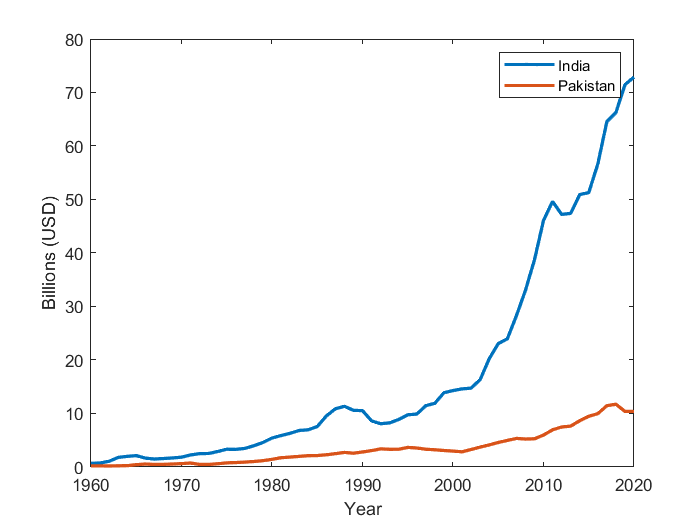

%plot data to help visualize trends

plot(timeline,india,'LineWidth',2)
hold on
plot(timeline,paki,'LineWidth',2)
%title("Military Spending by Year")
xlabel("Year")
ylabel("Billions (USD)")
legend("India", "Pakistan")
hold off

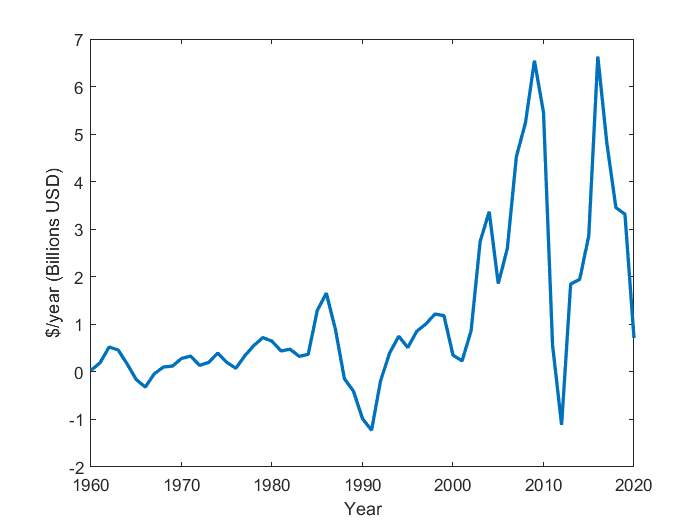


plot(timeline,indiaDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

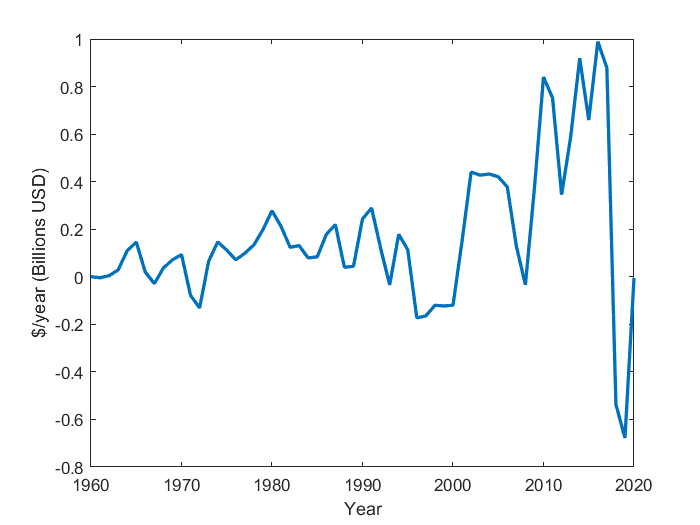


plot(timeline,pakiDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

%fit data to ecoConstraint model
[india_fit, india_gof] = ecoConstraintFit(india,paki,indiaDer);
[paki_fit, paki_gof] = ecoConstraintFit(paki,india,pakiDer);

indiaParam = coeffvalues(india_fit); %extract parameters
indiaInt = confint(india_fit); %confidence intervals
dIdt = @(I,P) ecoConstraint(I,P,indiaParam(1),indiaParam(2),indiaParam(3),indiaParam(4));

pakiParam = coeffvalues(paki_fit); %extract parameters
pakiInt = confint(paki_fit); %confidence intervals
dPdt = @(P,I) ecoConstraint(P,I,pakiParam(1),pakiParam(2),pakiParam(3),pakiParam(4));

%system of linear equations defing the fitted ecoConstraint model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%find fixed points of the fitted system
clear x y
syms x y;
[xFP(1,1),yFP(1,1)] = vpasolve([dIdt(x,y)==0,dPdt(y,x)==0],[x,y],[70 10]);
[xFP(2,1),yFP(2,1)] = vpasolve([dIdt(x,y)==0,dPdt(y,x)==0],[x,y]);

%Find the eigenvalues of the linearized system using the Jacobian
jac = jacobian([dIdt(x,y),dPdt(y,x)], [x y]);
eigval = zeros(2,length(xFP));
for i=1:length(xFP)
    temp = subs(jac,[x y],[xFP(i) yFP(i)]);
    eigval(:,i) = eig(temp);
end
eigval = eigval';

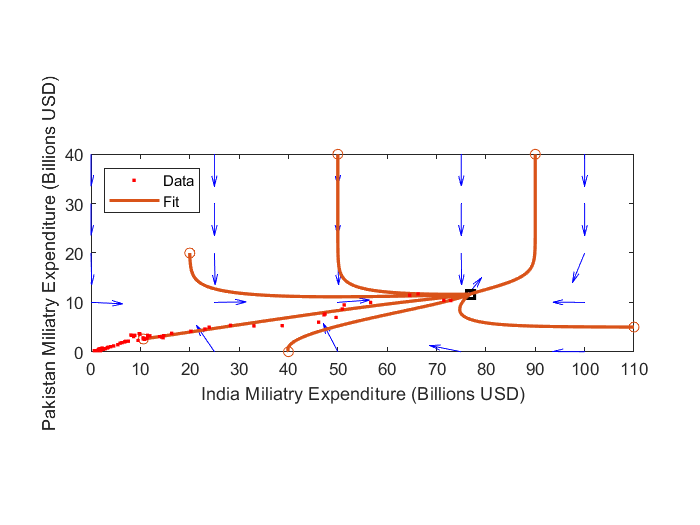

%plotting arrows
x1 = linspace(0,100,5);
y1 = linspace(0,40,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

arwlen = hypot(u, v);
quiver(x,y,u./arwlen,v./arwlen,'b',"AutoScaleFactor",0.3); figure(gcf)
xlabel("India Miliatry Expenditure (Billions USD)")
ylabel("Pakistan Miliatry Expenditure (Billions USD)")
axis tight equal;
hold on


% %plot fixed points in domain
fixedPoint = plot(xFP(1),yFP(1),'ks','LineWidth',2);
% plot(xFP(3),yFP(3),'ks','LineWidth',2)
% plot(xFP(4),yFP(4),'ks','LineWidth',2);

%plotting various trajectories
[~,ys] = ode45(f,[0;30],[40,0]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;30],[110;5]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;30],[20;20]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;30],[50;40]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;30],[90;40]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;30],[india(30),paki(30)]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%plot data
%plot(india(1),paki(1),'r.','LineWidth',2) %starting point
%plot(india(end),paki(end),'gs','LineWidth',2) %ending point
d = plot(india,paki,'r.');
%plot(indiaFP,pakiFP,'ks','LineWidth',2)


%title("Economic Constraint Model")
legend([d d2],"Data","Fit","Location",'northwest')
xlim([0 110])
ylim([0 40])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(india_gof.sse) + newline + ...
    "* R-Square " + num2str(india_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(india_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 108.5925
* R-Square 0.42596
* Root Mean Square Error 1.3803


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(paki_gof.sse) + newline + ...
    "* R-Square " + num2str(paki_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(paki_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 4.3648
* R-Square 0.22372
* Root Mean Square Error 0.27672


%see parameters
disp("lambda = " + num2str(indiaParam(1)) + " within 95% confidence of " + num2str(indiaInt(:,1)') + newline + ...
    "k = " + num2str(indiaParam(2)) + " within 95% confidence of " + num2str(indiaInt(:,2)') + newline + ...
    "a = " + num2str(indiaParam(3)) + " within 95% confidence of " + num2str(indiaInt(:,3)') + newline + ...
    "g = " + num2str(indiaParam(4)) + " within 95% confidence of " + num2str(indiaInt(:,4)') + newline + ...
    "lambda' = " + num2str(pakiParam(1)) + " within 95% confidence of " + num2str(pakiInt(:,1)') + newline + ...
    "k' = " + num2str(pakiParam(2)) + " within 95% confidence of " + num2str(pakiInt(:,2)') + newline + ...
    "a' = " + num2str(pakiParam(3)) + " within 95% confidence of " + num2str(pakiInt(:,3)') + newline + ...
    "g' = " + num2str(pakiParam(4))+ " within 95% confidence of " + num2str(pakiInt(:,4)'))

lambda = 4.3084e-05 within 95% confidence of -0.001513   0.0015991
k = 6.5327e-06 within 95% confidence of -0.000205  0.00021807
a = 0.43874 within 95% confidence of 0.22765     0.64982
g = -0.19074 within 95% confidence of -0.81726     0.43578
lambda' = 0.00013394 within 95% confidence of -0.0018863   0.0021542
k' = 9.9536e-05 within 95% confidence of -0.0012306   0.0014296
a' = 0.0098692 within 95% confidence of 0.0020632    0.017675
g' = 0.036497 within 95% confidence of -0.069964     0.14296


disp("Fixed points are found at:" + newline + ...
    "x* = " + num2str(double(xFP)) + ", y* = " + num2str(double(yFP)) + ", with eigenvalues: " + num2str(eigval))

    "Fixed points are found at:↵x* =  76.8294, y* =  11.6916, with eigenvalues: -0.56691    -0.77266"
    "Fixed points are found at:↵x* = -3.69287, y* = 0.434708, with eigenvalues: 0.065732   -0.065873"



### Military Spending (Smoothed)

We can try to improve the fit by smoothing the data with a rolling average.

indiaAve = movmean(india,5);
indiaAveDer = derivative(indiaAve,1,2);

pakiAve = movmean(paki,5);
pakiAveDer = derivative(pakiAve,1,2);

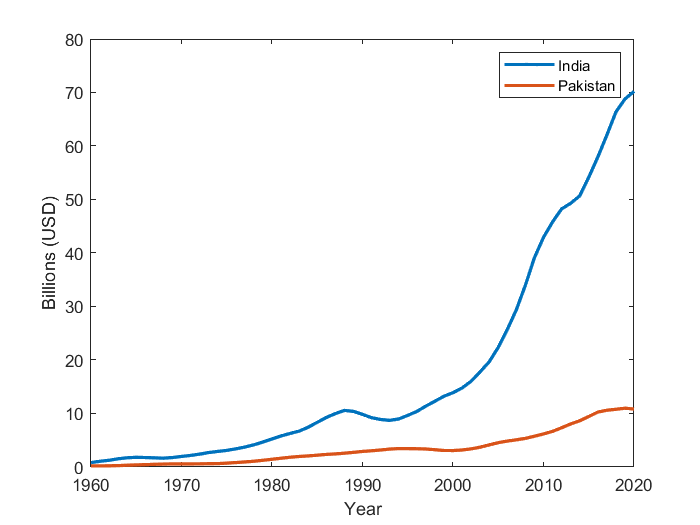

%plot data to help visualize trends

plot(timeline,indiaAve,'LineWidth',2)
hold on
plot(timeline,pakiAve,'LineWidth',2)
%title("Military Spending by Year (Smoothed)")
xlabel("Year")
ylabel("Billions (USD)")
legend("India", "Pakistan")
hold off

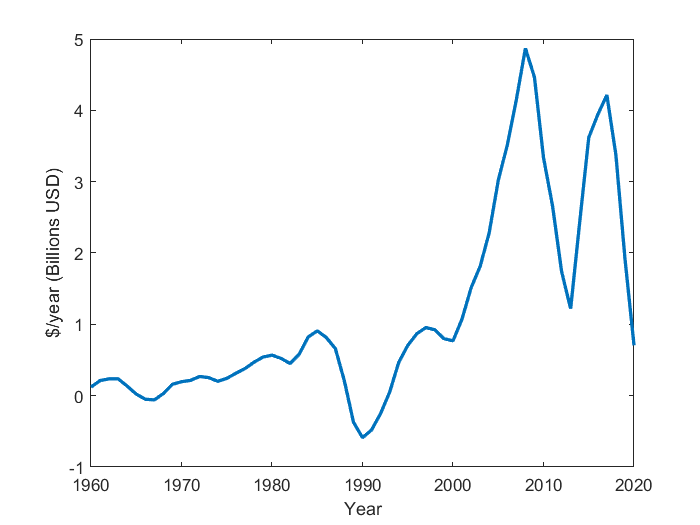


plot(timeline,indiaAveDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

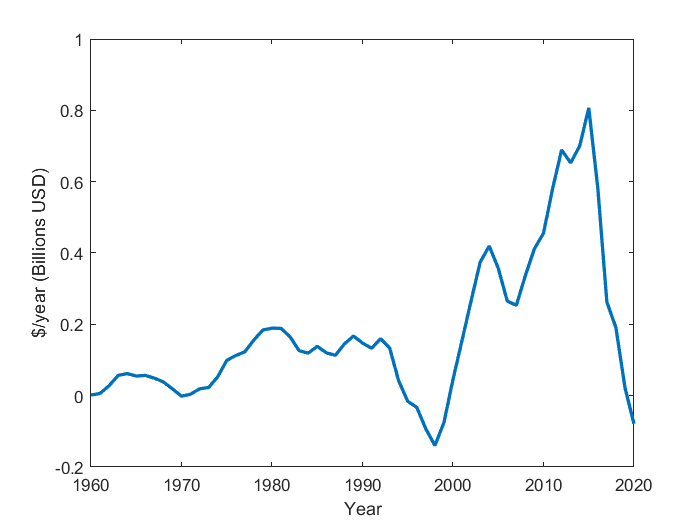


plot(timeline,pakiAveDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

%fit data to ecoConstraint model
[indiaAve_fit, indiaAve_gof] = ecoConstraintFit(indiaAve,pakiAve,indiaAveDer);
[pakiAve_fit, pakiAve_gof] = ecoConstraintFit(pakiAve,indiaAve,pakiAveDer);

indiaAveParam = coeffvalues(indiaAve_fit); %extract parameters
indiaAveInt = confint(indiaAve_fit); %confidence intervals
dIdt = @(I,P) ecoConstraint(I,P,indiaAveParam(1),indiaAveParam(2),indiaAveParam(3),indiaAveParam(4));

pakiAveParam = coeffvalues(pakiAve_fit); %extract parameters
pakiAveInt = confint(pakiAve_fit); %confidence intervals
dPdt = @(P,I) ecoConstraint(P,I,pakiAveParam(1),pakiAveParam(2),pakiAveParam(3),pakiAveParam(4));

%system of linear equations defing the fitted ecoConstraint model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%find fixed points of the fitted system
clear x y eigval
syms x y;
[xFP(1,1),yFP(1,1)] = vpasolve([dIdt(x,y)==0,dPdt(y,x)==0],[x,y],[70 10]);
[xFP(2,1),yFP(2,1)] = vpasolve([dIdt(x,y)==0,dPdt(y,x)==0],[x,y]);

%Find the eigenvalues of the linearized system using the Jacobian
jac = jacobian([dIdt(x,y),dPdt(y,x)], [x y]);
eigval = zeros(2,length(xFP));
for i=1:length(xFP)
    temp = subs(jac,[x y],[xFP(i) yFP(i)]);
    eigval(:,i) = eig(temp);
end
eigval = eigval';

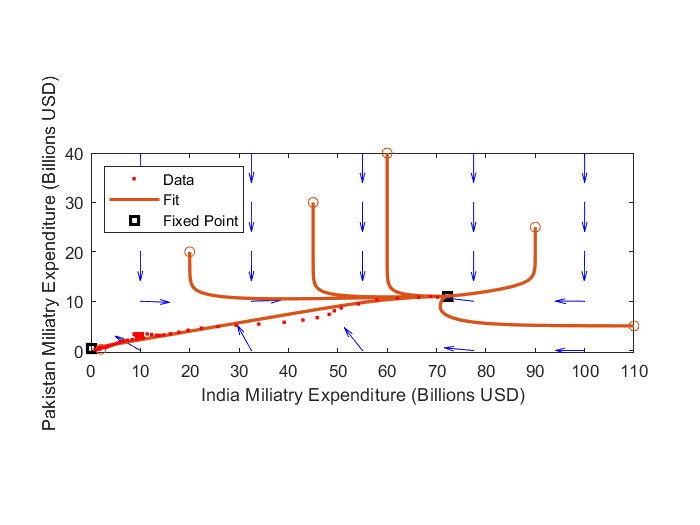

%plotting arrows
x1 = linspace(10,100,5);
y1 = linspace(0,40,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

arwlen = hypot(u, v); %normalize arrow lengths
quiver(x,y,u./arwlen,v./arwlen,'b',"AutoScaleFactor",0.3); figure(gcf)
xlabel("India Miliatry Expenditure (Billions USD)")
ylabel("Pakistan Miliatry Expenditure (Billions USD)")
axis tight equal;
hold on

%plot fixed points in domain
fixedPoint = plot(xFP(1),yFP(1),'ks','LineWidth',2);
plot(xFP(2),yFP(2),'ks','LineWidth',2)

%plotting various trajectories
%[~,ys] = ode45(f,[0;10],[2,0.5]);
%d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
%plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[110;5]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[90;25]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[20;20]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[45;30]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[60;40]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;100],[india(5);paki(5)]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%plot data
%plot(indiaAve(1),pakiAve(1),'r.','LineWidth',2) %starting point
%plot(indiaAve(end),pakiAve(end),'gs','LineWidth',2) %ending point
d = plot(indiaAve,pakiAve,'r.');
%plot(indiaAveFP,pakiAveFP,'ks','LineWidth',2)

%title("Economic Constraint Model (Smoothed)")
legend([d d2 fixedPoint],"Data","Fit","Fixed Point","Location",'northwest')
xlim([0 110])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaAve_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaAve_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaAve_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 43.5104
* R-Square 0.626
* Root Mean Square Error 0.87369


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiAve_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiAve_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiAve_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 0.67365
* R-Square 0.74155
* Root Mean Square Error 0.10871


%see parameters
disp("lambda = " + num2str(indiaAveParam(1)) + " within 95% confidence of " + num2str(indiaAveInt(:,1)') + newline + ...
    "k = " + num2str(indiaAveParam(2)) + " within 95% confidence of " + num2str(indiaAveInt(:,2)') + newline + ...
    "a = " + num2str(indiaAveParam(3)) + " within 95% confidence of " + num2str(indiaAveInt(:,3)') + newline + ...
    "g = " + num2str(indiaAveParam(4)) + " within 95% confidence of " + num2str(indiaAveInt(:,4)') + newline + ...
    "lambda' = " + num2str(pakiAveParam(1)) + " within 95% confidence of " + num2str(pakiAveInt(:,1)') + newline + ...
    "k' = " + num2str(pakiAveParam(2)) + " within 95% confidence of " + num2str(pakiAveInt(:,2)') + newline + ...
    "a' = " + num2str(pakiAveParam(3)) + " within 95% confidence of " + num2str(pakiAveInt(:,3)') + newline + ...
    "g' = " + num2str(pakiAveParam(4))+ " within 95% confidence of " + num2str(pakiAveInt(:,4)'))

lambda = 8.2687e-05 within 95% confidence of -0.0011552   0.0013206
k = 1.2566e-05 within 95% confidence of -0.00015676  0.00018189
a = 0.45339 within 95% confidence of 0.31033     0.59644
g = -0.23087 within 95% confidence of -0.63837     0.17663
lambda' = 3.905e-06 within 95% confidence of -4.9384e-05  5.7194e-05
k' = 4.3984e-06 within 95% confidence of -4.8269e-05  5.7066e-05
a' = 0.013375 within 95% confidence of 0.010738    0.016012
g' = -0.0011621 within 95% confidence of -0.042611    0.040287


disp("Fixed points are found at:" + newline + ...
    "x* = " + num2str(double(xFP)) + ", y* = " + num2str(double(yFP)) + ", with eigenvalues: " + num2str(eigval))

    "Fixed points are found at:↵x* =   72.1362, y* =  11.0235, with eigenvalues: -0.70835     -1.1015"
    "Fixed points are found at:↵x* = 0.0871135, y* = 0.509222, with eigenvalues: 0.077862   -0.077883"



The dynamics of the sytem remained unchanged by smoothing the data.

### Military Spending (%) (Smoothed Data)

Analyze India's and Pakistan's military spending as a percent of GDP.

%extract data for India and find the derivatives of the list 
indiaIdx = percentFull.CountryName == 'India';
indiaPer = movmean(percentFull{indiaIdx, vartype('numeric')},5);
indiaPerDer = derivative(indiaPer,1,2);

%extract data for Pakistan and find the derivatives of the list 
pakiIdx = percentFull.CountryName == 'Pakistan';
pakiPer = movmean(percentFull{pakiIdx, vartype('numeric')},5);
pakiPerDer = derivative(pakiPer,1,2);

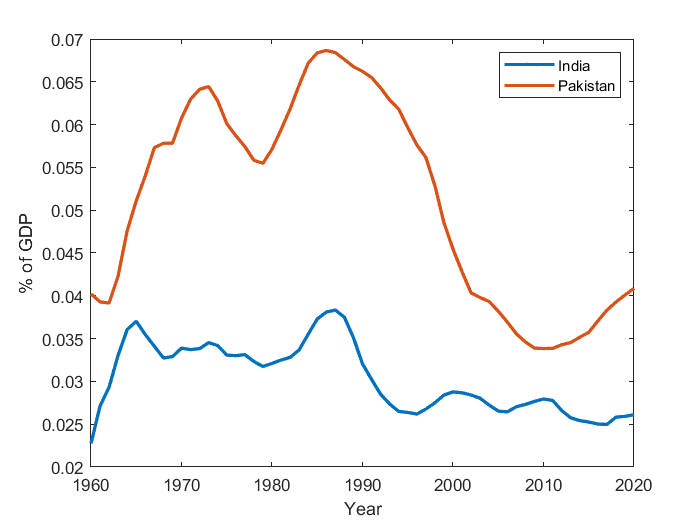

%plot data to help visualize trends

plot(timeline,indiaPer,'LineWidth',2)
hold on
plot(timeline,pakiPer,'LineWidth',2)
%title("Military Spending by Year (Smoothed)")
xlabel("Year")
ylabel("% of GDP")
legend("India", "Pakistan")
hold off

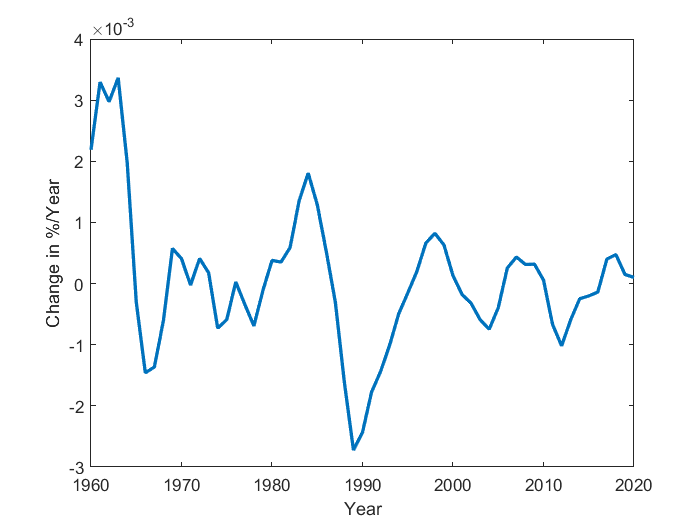


plot(timeline,indiaPerDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("Change in %/Year")

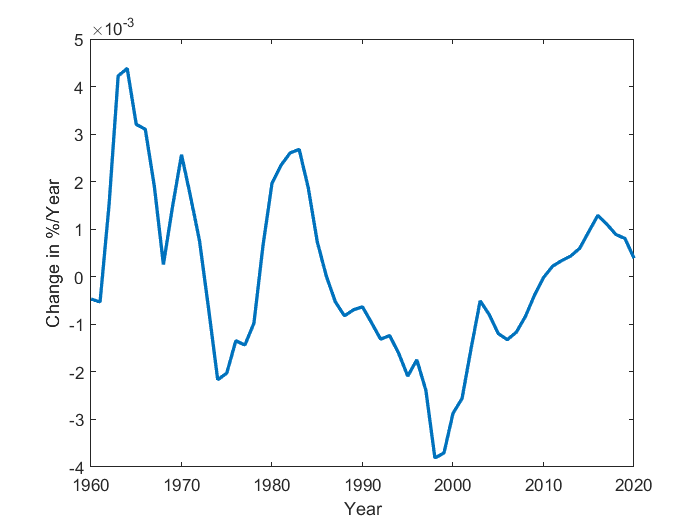


plot(timeline,pakiPerDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("Change in %/Year")

%fit data to ecoConstraint model
[indiaPer_fit, indiaPer_gof] = ecoConstraintFit(indiaPer,pakiPer,indiaPerDer);
[pakiPer_fit, pakiPer_gof] = ecoConstraintFit(pakiPer,indiaPer,pakiPerDer);

indiaPerParam = coeffvalues(indiaPer_fit); %extract parameters
indiaPerInt = confint(indiaPer_fit); %confidence intervals
dIdt = @(I,P) ecoConstraint(I,P,indiaPerParam(1),indiaPerParam(2),indiaPerParam(3),indiaPerParam(4));

pakiPerParam = coeffvalues(pakiPer_fit); %extract parameters
pakiPerInt = confint(pakiPer_fit); %confidence intervals
dPdt = @(P,I) ecoConstraint(P,I,pakiPerParam(1),pakiPerParam(2),pakiPerParam(3),pakiPerParam(4));

%system of linear equations defing the fitted ecoConstraint model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%find fixed points of the fitted system
clear x y eigval
syms x y;
[xFP(1,1),yFP(1,1)] = vpasolve([dIdt(x,y)==0,dPdt(y,x)==0],[x,y],[70 10]);

%Find the eigenvalues of the linearized system using the Jacobian
jac = jacobian([dIdt(x,y),dPdt(y,x)], [x y]);
eigval = zeros(2,length(xFP));
for i=1:length(xFP)
    temp = subs(jac,[x y],[xFP(i) yFP(i)]);
    eigval(:,i) = eig(temp);
end
eigval = eigval';

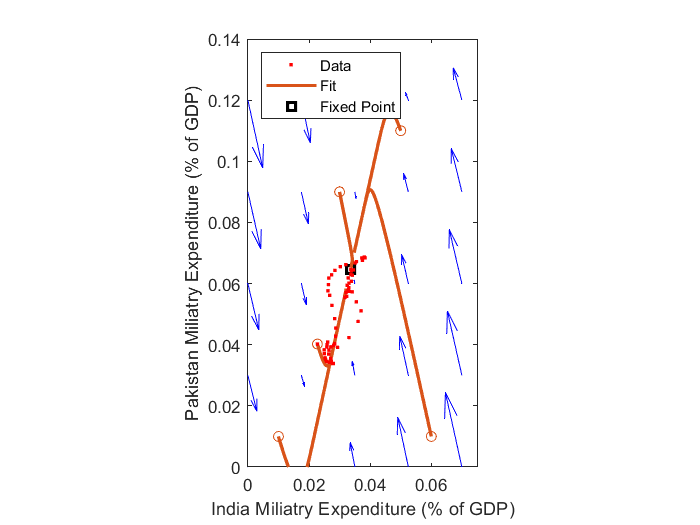

%plotting arrows
x1 = linspace(0,0.07,5);
y1 = linspace(0,0.12,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India Miliatry Expenditure (% of GDP)")
ylabel("Pakistan Miliatry Expenditure (% of GDP)")
axis tight equal;
hold on


%plot fixed points in domain
fixedPoint = plot(xFP(1),yFP(1),'ks','LineWidth',2);
% plot(xFP(2),yFP(2),'ks','LineWidth',2)
% plot(xFP(3),yFP(3),'ks','LineWidth',2)
% plot(xFP(4),yFP(4),'ks','LineWidth',2)

%plotting various trajectories
[~,ys] = ode45(f,[0;200],[indiaPer(1),pakiPer(1)]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;200],[0.01;0.01]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;200],[0.03;0.09]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;200],[0.05;0.11]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;200],[0.06;0.01]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%plot data
%plot(indiaPer(1),pakiPer(1),'r.','LineWidth',2) %starting point
%plot(indiaPer(end),pakiPer(end),'gs','LineWidth',2) %ending point
d = plot(indiaPer,pakiPer,'r.');
%plot(indiaPerFP,pakiPerFP,'ks','LineWidth',2)


%title("Economic Constraint Model (Smoothed)")
legend([d d2 fixedPoint],"Data","Fit","Fixed Point","Location",'northwest')
xlim([0 0.075])
ylim([0 0.14])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaPer_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaPer_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaPer_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 8.8046e-05
* R-Square -0.074243
* Root Mean Square Error 0.0012428


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiPer_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiPer_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiPer_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 0.00014246
* R-Square 0.27635
* Root Mean Square Error 0.0015809


%see parameters
disp("lambda = " + num2str(indiaPerParam(1)) + " within 95% confidence of " + num2str(indiaPerInt(:,1)') + newline + ...
    "k = " + num2str(indiaPerParam(2)) + " within 95% confidence of " + num2str(indiaPerInt(:,2)') + newline + ...
    "a = " + num2str(indiaPerParam(3)) + " within 95% confidence of " + num2str(indiaPerInt(:,3)') + newline + ...
    "g = " + num2str(indiaPerParam(4)) + " within 95% confidence of " + num2str(indiaPerInt(:,4)') + newline + ...
    "lambda' = " + num2str(pakiPerParam(1)) + " within 95% confidence of " + num2str(pakiPerInt(:,1)') + newline + ...
    "k' = " + num2str(pakiPerParam(2)) + " within 95% confidence of " + num2str(pakiPerInt(:,2)') + newline + ...
    "a' = " + num2str(pakiPerParam(3)) + " within 95% confidence of " + num2str(pakiPerInt(:,3)') + newline + ...
    "g' = " + num2str(pakiPerParam(4))+ " within 95% confidence of " + num2str(pakiPerInt(:,4)'))

lambda = 0.79618 within 95% confidence of -4448.6322      4450.2245
k = 0.079147 within 95% confidence of -1.2882      1.4465
a = 0.0154 within 95% confidence of -0.023181     0.05398
g = 0.0016656 within 95% confidence of -0.019133    0.022464
lambda' = 0.16263 within 95% confidence of -34.9855      35.3107
k' = 0.080718 within 95% confidence of -0.34689     0.50833
a' = 0.33876 within 95% confidence of 0.19297     0.48455
g' = -0.0060699 within 95% confidence of -0.01702   0.0048799


disp("Fixed points are found at:" + newline + ...
    "x* = " + num2str(double(xFP)) + ", y* = " + num2str(double(yFP)) + ", with eigenvalues: " + num2str(eigval))

    "Fixed points are found at:↵x* = 0.033551, y* = 0.064565, with eigenvalues: -0.0091246    -0.15363"
    "Fixed points are found at:↵x* = 0.087113, y* =  0.50922, with eigenvalues:  -0.018657    -0.16511"



### Nuclear Arms Race

dataLines = [2, Inf];
filename = "number-of-nuclear-warheads-in-the-inventory-of-the-nuclear-powers.csv";
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Entity", "Code", "Year", "Count"];
opts.VariableTypes = ["categorical", "categorical", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Entity", "Code"], "EmptyFieldRule", "auto");

% Import the data
nukeRaw = readtable(filename, opts);

clear opts filename datalines

timelineNuke = 1998:2017;

%Pakistan's nukes
pakiIdx = nukeRaw.Entity == 'Pakistan' & nukeRaw.Year>=1998;
pakiNuke = nukeRaw.Count(pakiIdx);

%India's nukes during the cold war
indiaIdx = nukeRaw.Entity == 'India' & nukeRaw.Year>=1998;
indiaNuke = nukeRaw.Count(indiaIdx);

%change in nuclear stockpile with time
indiaNukeDer = derivative(indiaNuke,1,1);

pakiNukeDer = derivative(pakiNuke,1,1);

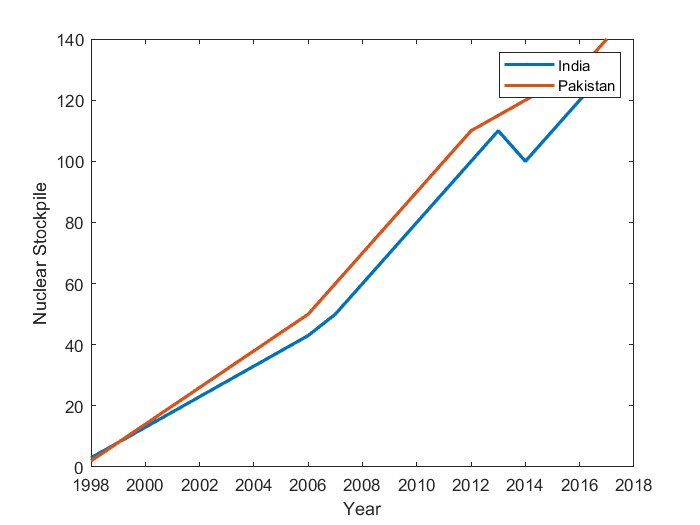

plot(timelineNuke,indiaNuke,"LineWidth",2);
hold on
plot(timelineNuke,pakiNuke,"LineWidth",2)
legend("India","Pakistan")
xlabel("Year")
ylabel("Nuclear Stockpile")
hold off

%fit data to Economic Constraint model
[indiaNuke_fit, indiaNuke_gof] = ecoConstraintFit(indiaNuke,pakiNuke,indiaNukeDer);
[pakiNuke_fit, pakiNuke_gof] = ecoConstraintFit(pakiNuke,indiaNuke,pakiNukeDer);

indiaNukeParam = coeffvalues(indiaNuke_fit); %extract parameters
indiaNukeInt = confint(indiaNuke_fit); %confidence intervals
dINdt = @(I,P) ecoConstraint(I,P,indiaNukeParam(1),indiaNukeParam(2),indiaNukeParam(3),indiaNukeParam(4));

pakiNukeParam = coeffvalues(pakiNuke_fit); %extract parameters
pakiNukeInt = confint(pakiNuke_fit); %confidence intervals
dPNdt = @(P,I) ecoConstraint(P,I,pakiNukeParam(1),pakiNukeParam(2),pakiNukeParam(3),pakiNukeParam(4));

%system of linear equations defing the fitted Economic Constraint model
f = @(t,X) [dINdt(X(1),X(2)); dPNdt(X(2),X(1))];

%find fixed points of the fitted system
clear x y eigval
syms x y;
[xFP(1,1),yFP(1,1)] = vpasolve([dINdt(x,y)==0,dPNdt(y,x)==0],[x,y],[150 150]);
[xFP(2,1),yFP(2,1)] = vpasolve([dINdt(x,y)==0,dPNdt(y,x)==0],[x,y]);

%Find the eigenvalues of the linearized system using the Jacobian
jac = jacobian([dINdt(x,y),dPNdt(y,x)], [x y]);
eigval = zeros(2,length(xFP));
for i=1:length(xFP)
    temp = subs(jac,[x y],[xFP(i) yFP(i)]);
    eigval(:,i) = eig(temp);
end
eigval = eigval';

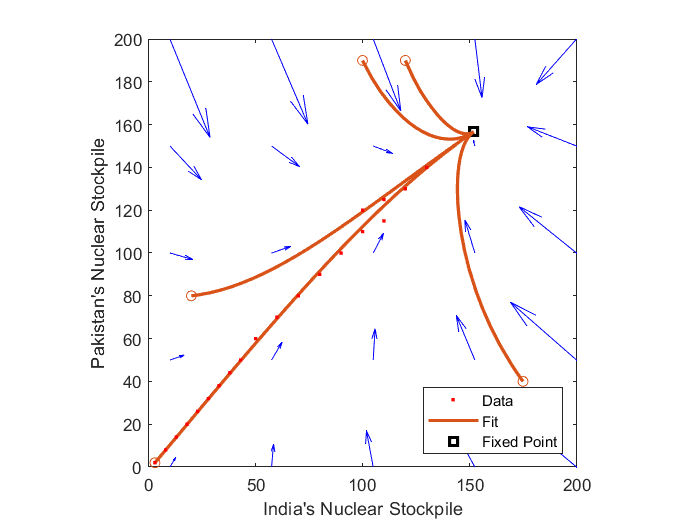

%plotting arrows
x1 = linspace(10,200,5);
y1 = linspace(0,200,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India's Nuclear Stockpile")
ylabel("Pakistan's Nuclear Stockpile")
axis tight equal;
hold on

%plot fixed points in domain
fixedPoint = plot(xFP(1),yFP(1),'ks','LineWidth',2);
% plot(xFP(2),yFP(2),'ks','LineWidth',2)


%plotting various trajectories
[~,ys] = ode45(f,[0;24],[indiaNuke(1),pakiNuke(1)]); %63 years from 1998
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%[~,ys] = ode45(f,[0;20],[110,80]);
%plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
%plot(ys(1,1),ys(1,2),'bo') % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[20,80]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[100,190]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[175,40]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;20],[120,190]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point


%plot data
%plot(indiaNuke(1),pakiNuke(1),'r.','LineWidth',2) %starting point
%plot(indiaNuke(end),pakiNuke(end),'gs','LineWidth',2) %ending point
d = plot(indiaNuke,pakiNuke,'r.');
%fp = plot(indiaNukeFP,pakiNukeFP,'ks','LineWidth',2);


%title("Economic Constraint Model (Nuclear Weapons)")
legend([d d2 fixedPoint],"Data","Fit","Fixed Point",'Location','southeast')
xlim([0 200])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaNuke_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaNuke_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaNuke_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 168.71
* R-Square 0.18909
* Root Mean Square Error 3.2472


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiNuke_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiNuke_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiNuke_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 35.9629
* R-Square 0.57839
* Root Mean Square Error 1.4992


%see parameters
disp("lambda = " + num2str(indiaNukeParam(1)) + " within 95% confidence of " + num2str(indiaNukeInt(:,1)') + newline + ...
    "k = " + num2str(indiaNukeParam(2)) + " within 95% confidence of " + num2str(indiaNukeInt(:,2)') + newline + ...
    "a = " + num2str(indiaNukeParam(3)) + " within 95% confidence of " + num2str(indiaNukeInt(:,3)') + newline + ...
    "g = " + num2str(indiaNukeParam(4)) + " within 95% confidence of " + num2str(indiaNukeInt(:,4)') + newline + ...
    "lambda' = " + num2str(pakiNukeParam(1)) + " within 95% confidence of " + num2str(pakiNukeInt(:,1)') + newline + ...
    "k' = " + num2str(pakiNukeParam(2)) + " within 95% confidence of " + num2str(pakiNukeInt(:,2)') + newline + ...
    "a' = " + num2str(pakiNukeParam(3)) + " within 95% confidence of " + num2str(pakiNukeInt(:,3)') + newline + ...
    "g' = " + num2str(pakiNukeParam(4))+ " within 95% confidence of " + num2str(pakiNukeInt(:,4)'))

lambda = 1.3326 within 95% confidence of -23.4313      26.0965
k = 0.023686 within 95% confidence of -0.28153      0.3289
a = 0.096128 within 95% confidence of -0.28735      0.4796
g = 3.4963 within 95% confidence of -0.29305      7.2856
lambda' = 1.9578 within 95% confidence of -7.55661      11.4721
k' = 0.033898 within 95% confidence of -0.084746     0.15254
a' = 0.15589 within 95% confidence of -0.060565     0.37234
g' = 3.8692 within 95% confidence of 1.8995       5.839


disp("Fixed points are found at:" + newline + ...
    "x* = " + num2str(double(xFP)) + ", y* = " + num2str(double(yFP)) + ", with eigenvalues: " + num2str(eigval))

    "Fixed points are found at:↵x* =  152.0992, y* =  156.7358, with eigenvalues: -0.28688    -0.57817"
    "Fixed points are found at:↵x* = -31.34126, y* = -42.29172, with eigenvalues:  0.10749    -0.13736"



## Useful Functions

function dx = derivative(X,t,dim)
  % X (vector or 2D array), t (scalar), dim (scalar)
  %
  % Computes the numerical derivatives from a list of data points, X, with
  % a time step, t, using the secant method.
  %   dx/dt = (f(X(i+1))-f(X(i-1)))/2t
  %
  % End cases are special:
  %   dx (first) = (second entry - current entry)/2t
  %   dx (end) = (last entry - second to last entry)/2t
  %
  % Error of t^2
  
  if dim==1
    dx = zeros(size(X));
      
    dx(1,:) = (X(2,:)-X(1,:))/(2*t);
    dx(end,:) = (X(end,:)-X(end-1,:))/(2*t);
    for i=2:size(X,1)-1
      dx(i,:) = (X(i+1,:)-X(i-1,:))/(2*t);
    end
  elseif dim==2
    dx = zeros(size(X));
    
    dx(:,1) = (X(:,2)-X(:,1))/(2*t);
    dx(:,end) = (X(:,end)-X(:,end-1))/(2*t);
    for i=2:size(X,2)-1
      dx(:,i) = (X(:,i+1)-X(:,i-1))/(2*t);
    end
  else
    error("The \'dim\' argument must be 1 or 2, X must be a vector or a 2D array.")
  end
end